# This script plots data from mods

close all
clear all
colormap parula
theseFiles = dir('./behavioral_data_raw/MODS_data/*.mat')  ;
ser_pos = nan(length(theseFiles), 6);
span_acc = nan(length(theseFiles), 4);

for xx = 1:length(theseFiles)
    load(['./behavioral_data_raw/MODS_data/' theseFiles(xx).name]);
    
    [pos, acc] = mods_analysis(Record, 0);
    
    span_acc(xx,1:4) = acc;
    ser_pos(xx, 1:6) = pos;
    
end

## plot serial position means

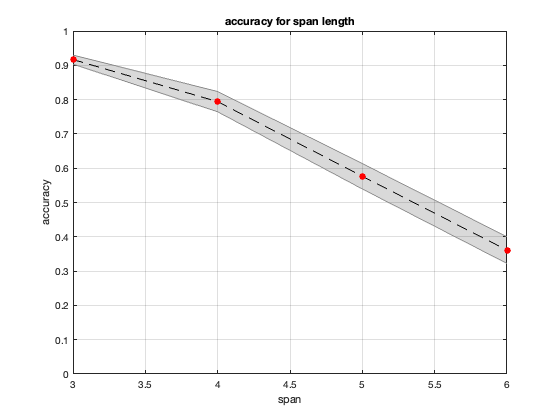

mean_span_acc = mean(span_acc);
err_span_acc = std(span_acc) / sqrt(length(span_acc));

shadedErrorBar(3:6,mean_span_acc,err_span_acc,'--k',1)
hold on
grid on
plot(3:6,mean_span_acc, ...
    '.r', ...
    'LineWidth', 2,...
    'MarkerSize',23, ...
    'MarkerFaceColor','k')
ylim([0 1])


xlabel('span')
ylabel('accuracy')
title('accuracy for span length')

## plot serial position

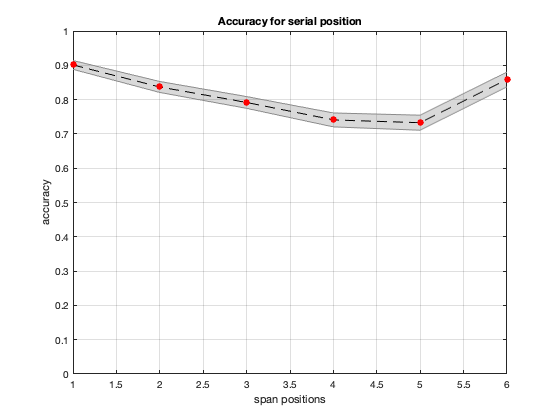

figure
mean_ser = mean(ser_pos);
err_ser = std(ser_pos) / sqrt(length(ser_pos));

shadedErrorBar(1:6,mean_ser,err_ser,'--k',1)
hold on 
grid on
plot(1:6,mean_ser, ...
    '.r', ...
    'LineWidth', 2,...
    'MarkerSize',23, ...
    'MarkerFaceColor','r')
ylim([0 1])
xlabel('span positions')
ylabel('accuracy')
title('Accuracy for serial position')